# Attacking Learn++.NSE

In this notebook we will be attacking Learn++.NSE. 

The types of attacks are

- Create a model to predict the future locations of cluster centroids using SINDy. From the predicted clusters at timestep $t$, use AdvLearn to generate attack points. Insert those attack points into the training data of $t$.

- Create a model to predict the future locations of cluster centroids using SINDy. From the predicted clusters at timestep $t$, randomly select points, flip their labels. Insert those attack points into the training data of $t$.

- Based on the actual clusters from timestep $t_{\text{past}}$ generate attack points using AdvLearn. Insert those attack points into the training data of current time step. 

For all attacks we are assuming we do not know the labels of the incoming clusters until they have been classified by Learn++.NSE. So to attack a particular timestep, either predict where the clusters will be and generate attack points accordingly. Alternatively, we could generate attacks based on the clusters of previous timesteps. 

pathsForCode();
dataset = "X2CDT";
kernel = "Linear";
lambda = 8e-3;
polyOrder = 1;
useSine = 0;
sineMultiplier = 10;
useExp = 0;
expMultiplier = 10;
maxSteps = 250;
stepSize = 5;
degree = 3;
coef0 = 1;
c = 1; % Class to attack
numAtkPts = 40;

[nseData_Baseline,nseResults_Baseline,...
	   ~,~,~,~] = ...
	   LearnPlusPLusNSE_Baseline(dataset,... % General setting
                                     kernel); 

[classInfo_AdvLearnSINDy,...
nseData_AdvLearnSINDy,nseResults_AdvLearnSINDy,...
numClasses,numDims,numObs,numTimesSteps,...
SINDyData_AdvLearnSINDy,SINDyResults_AdvLearnSINDy,...
atkData_AdvLearnSINDy,genDistr_AdvLearnSINDy] = ...
...
attackingLearnPlusPlus_chrisAttack_SINDy(dataset,... % General setting
                                        kernel,... % Learn++.NSE & AttackSVM setting
                                        lambda,polyOrder,... % SINDy Setting
                                        useSine,sineMultiplier,... % SINDy Setting
                                        useExp,expMultiplier,... % SINDy Setting
                                        maxSteps,stepSize,... % AttackSVM setting
                                        degree,coef0,... % AttackSVM setting
                                        numAtkPts,c); % AttackSVM setting

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40



                                         

timeStepsInPastToAttack = 4;
[nseData_AdvLearn,nseResults_AdvLearn,...
~,~,~,~,...
atkData_AdvLearn] = attackingLearnPlusPlus_AdvLearn(dataset,... % General setting
                                           kernel,... % Learn++.NSE & AttackSVM setting
    		                           maxSteps,stepSize,... % AttackSVM setting
                		           degree,coef0,... % AttackSVM setting
                		           numAtkPts,... % AttackSVM setting
                                           timeStepsInPastToAttack,c); % AttackSVM setting

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40



## Results

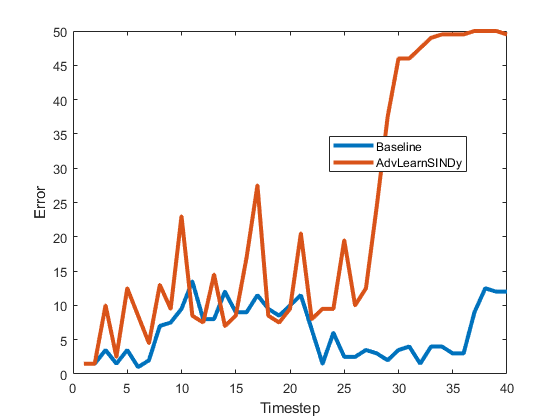

AdvLearnError = [nseResults_AdvLearn(1:40).errs_nse];
AdvLearnSINDyError = [nseResults_AdvLearnSINDy(1:40).errs_nse];
BaselineError = [nseResults_Baseline(1:40).errs_nse];

Error(1,:) = BaselineError;
Error(2,:) = AdvLearnSINDyError;
%Error(3,:) = AdvLearnError;
figure
plot((1:40)',Error'*100,'LineWidth',3)
xlabel('Timestep')
ylabel('Error')
legend('Baseline','AdvLearnSINDy','Location','best')

### AdvLearn With SINDy 

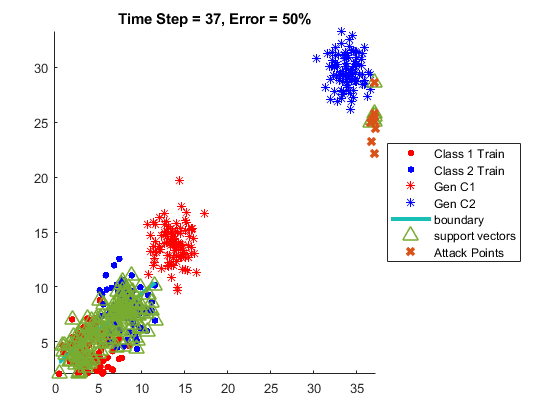

timeStep = 37;
svmNumber = 1;
svmMatch = true;
plotGenData = true;
plotPrevdata = true;
plotResultsAdvLearnSINDy(genDistr_AdvLearnSINDy,atkData_AdvLearnSINDy,nseResults_AdvLearnSINDy,timeStep,svmNumber,svmMatch,nseData_AdvLearnSINDy,plotGenData)

### AdvLearn

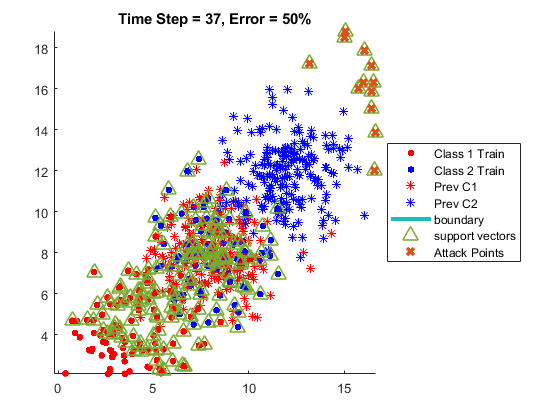

plotResultsAdvLearn(atkData_AdvLearn,nseResults_AdvLearn,timeStep,svmNumber,svmMatch,nseData_AdvLearn,timeStepsInPastToAttack,plotPrevdata)

### Quantifying SINDy

SINDyResults = SINDyResults_AdvLearnSINDy;
NseData = nseData_AdvLearnSINDy;
GenDistr = genDistr_AdvLearnSINDy;
ClassInfo = classInfo_AdvLearnSINDy;
% Quantify accuracy of SINDy with KL Divergence
for iTStep = 3:NumTimeSteps
for iClass = 1:NumClasses
    Idx = ClassInfo(iTStep,iClass).idx;
    RealDistr = NseData(iTStep).dataTrain(Idx,:);
    PredDistr = GenDistr(iTStep).data(Idx,:);
    MixDistr = 0.5*(RealDistr+PredDistr); % For JS Div
    PredMu = mean(PredDistr); 
    PredCov = cov(PredDistr);
    RealCov = cov(RealDistr);
    RealMu = mean(RealDistr);
    MixMu = mean(MixDistr);
    MixCov = cov(MixDistr);
    Cov1 = PredCov;
    Cov0 = RealCov;
    Mu1 = PredMu;
    Mu0 = RealMu;
    k = numDims;
%                 PredDistrPDF(iClass).Data = mvnpdf(PredDistr,PredMu,PredCov);
%                 RealDistrPDF(iClass).Data = mvnpdf(RealDistr,RealMu,RealCov);
    SINDyResults(iTStep,iClass).HellDist = HellingerDistance(Mu1,Mu0,Cov1,Cov0);
    SINDyResults(iTStep,iClass).KLDiv = KLDivergence(Mu1,Mu0,Cov1,Cov0,k);
    SINDyResults(iTStep,iClass).JSDiv = JSDivergence(Mu1,Mu0,MixMu,Cov1,Cov0,MixCov,k);
end
end
for iClass= 1:numClasses
    SINDyMetric.HellDist.("c"+iClass) = vertcat(SINDyResults(:,iClass).HellDist);
    SINDyMetric.KLDiv.("c"+iClass) = vertcat(SINDyResults(:,iClass).KLDiv);
    SINDyMetric.JSDiv.("c"+iClass) = vertcat(SINDyResults(:,iClass).JSDiv);
end

### Hellinger Distance

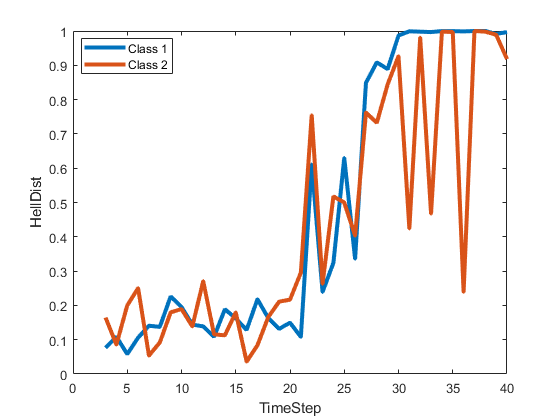

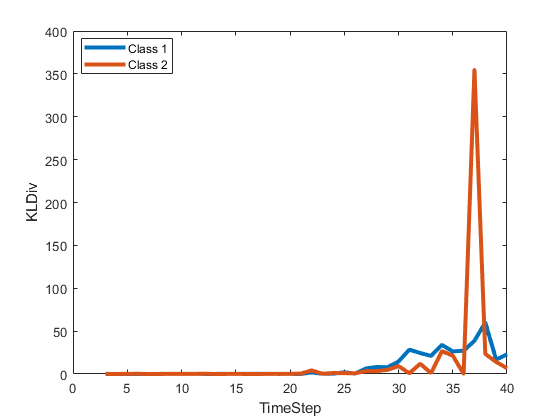

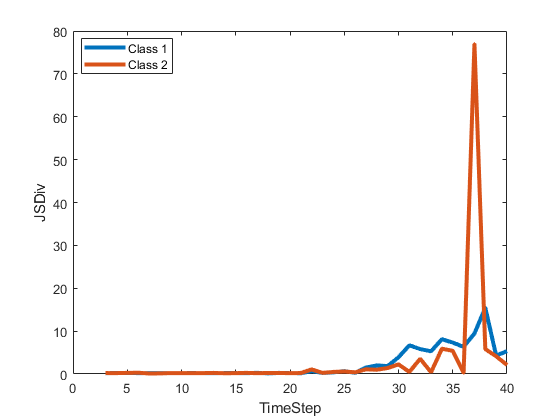

for i = ["HellDist" "KLDiv" "JSDiv"]
figure
plot((3:NumTimeSteps),[SINDyMetric.(i).c1 SINDyMetric.(i).c2],"LineWidth",3)
xlabel("TimeStep")
ylabel(i)
legend("Class "+(1:numClasses),"Location","best")
end

### JS Divergence

### KL Divergence

Functions for calculations

function Div = KLDivergence(Mu1,Mu0,Cov1,Cov0,k)
Div = 0.5*(trace(inv(Cov1)*Cov0)+(Mu1-Mu0)*inv(Cov1)*(Mu1-Mu0)'-k+log(det(Cov1)/det(Cov0)));
end

function Dist = HellingerDistance(Mu1,Mu0,Cov1,Cov0)
Dist = sqrt(1 - ((det(Cov1)^(1/4)*det(Cov0)^(1/4))/det((Cov1+Cov0)/2)^(1/2))*exp((-1/8)*(Mu1-Mu0)*inv((Cov1+Cov0)/2)*(Mu1-Mu0)'));
end

function Div = JSDivergence(Mu1,Mu0,MixMu,Cov1,Cov0,MixCov,k)
    Div = 0.5*(KLDivergence(Mu1,MixMu,Cov1,MixCov,k) + KLDivergence(Mu0,MixMu,Cov0,MixCov,k));
end